# ECSE 343: Numerical Methods for Engineers- Assignment 1- part b

Due Date: 21st Feb. 2023

Student Name: Chenyi Xu

Student ID:    260948311

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: Cancellation Errors **(10 marks)**

a) Given the equation $x^2 + 2 bx  -1=0$ where $b$ is a parameter chosen such that $b> 0$. Using the quadratic formula the roots $x_1$ and $x_2$ of this equation are given by $x=-b\pm\sqrt{b^2 +1}$ . The following MATLAB program computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$. Run the code and explain the behavior shown in the plot. In particular, explain why the value computed for $x_1$ appears inaccurate for large values of $b$.

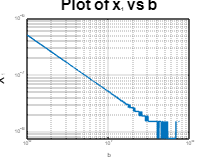



b = logspace(6,8,1000);

x1 = -b+sqrt(b.^2 +1);
x2 = -b-sqrt(b.^2 +1);



%plot x1 on a loglog scale

figure
loglog(b,x1)
title({'Question 1a';'Plot of x_1 vs b'})
xlabel('b')
ylabel('x_1')
grid on

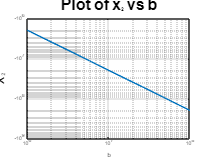



%plot x2 on a loglog scale

figure
loglog(b,x2)
xlabel('b')
ylabel('x_2')
title({'Question 1a';'Plot of x_2 vs b'})
grid on

*For very large values of b, b and -b will get cancel out and lead to loss of significant digits and precision. The cancellation error are then resulted. *

b) Prove that the product of roots $x_1x_2=(-b+\sqrt{b^2 +1})(-b-\sqrt{b^2 +1})=-1$ for all $b> 0$.

*    % type up your solution here*

*x1x2 = *$b^2 +b\sqrt{b^2 +1}-b\sqrt{b^2 +1}-\left(b^2 +1\right)=-1$

Therefore, the product of roots x1 and x2 is always -1 for all b>0. 

c) Write a script that computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$ (same as in part a. above) which does not suffer from numerical illconditioning.

% write your program here 

b = logspace(6,8,1000);

%% Put your code for computing x1 and x2 below

% x1 = -1/x2
x2 = -b-sqrt(b.^2 +1);
x1 = -1 ./x2

x1 = 1.0e-06 *

    0.5000    0.4977    0.4954    0.4931    0.4909    0.4886    0.4864    0.4841    0.4819    0.4797    0.4775    0.4753    0.4731    0.4709    0.4688    0.4666    0.4644    0.4623    0.4602    0.4581    0.4560    0.4539    0.4518    0.4497    0.4476    0.4456    0.4435    0.4415    0.4395    0.4374    0.4354    0.4334    0.4314    0.4294    0.4275    0.4255    0.4235    0.4216    0.4197    0.4177    0.4158    0.4139    0.4120    0.4101    0.4082    0.4063    0.4045    0.4026    0.4008    0.3989


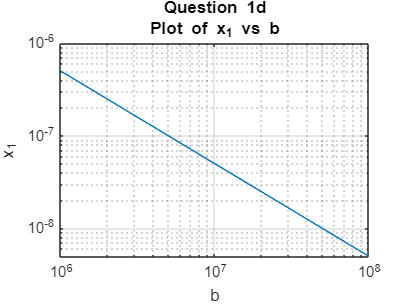


%plot x1 on a loglog scale
figure(1)
loglog(b,x1)
xlabel('b')
ylabel('x_1')
grid on
title({'Question 1d';'Plot of x_1 vs b'})

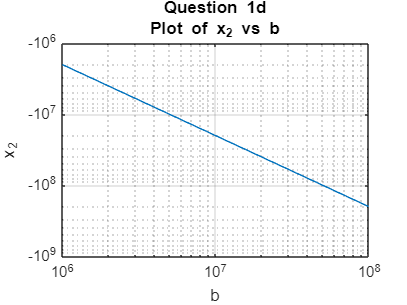


%plot x2 on a loglog scale
figure(2)
loglog(b,x2)
xlabel('b')
ylabel('x_2')
grid on
title({'Question 1d';'Plot of x_2 vs b'})

## Question 2:  Cholesky Least Squares Estimation **(10 marks)**

(a) **Cholesky factorization **is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix$\mathit{\mathbf{M}}$must satisfy following two conditions:

     1. The matrix $\mathit{\mathbf{M}}$must be symmetric, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. The matrix $\mathit{\mathbf{M}}$ must be positive definite,  i.e.  ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$, $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

If the above two conditons are met then the matrix $\mathit{\mathbf{M}}$ can be factored as 


$$\mathit{\mathbf{M}}=\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^T$$
                 

where $\mathit{\mathbf{L}}$ is a $N\times N$the lower triangular matrix with real and positive diagonal enteries. The enteries of matrix $\mathit{\mathbf{L}}$ are given by the following expression 


$$\textbf{L}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{j,j} - \sum_{k=1}^{j-1} \textbf{L}_{j,k}^2 }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{L}_{j,j}} \left(\textbf{M}_{i,j} - \sum_{k=1}^{j-1} \textbf{L}_{i,k} \textbf{L}_{j,k} \right),              & \text{if  } i>j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm, the use the outline of the function named *CholeskyDecomposition* provided in the appendix.

Use the cell below to test your Cholesky decompostion code by computing the Frobenius norm of  $\left.{\left(\mathit{\mathbf{L}}\right.}^{\;} {\mathit{\mathbf{L}}}^T -M\right)\ldotp$

M= [2 -1 0; -1 2 -1; 0 -1 2];

L = CholeskyDecompositon(M)

L =     1.4142         0         0
   -0.7071    1.2247         0
         0   -0.8165    1.1547




Error =  norm(L*L'-M)

Error = 4.4409e-16

 b) In regression problems we ofthen need to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$.  Show that the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is symmetric positive definite, and thus can be factored using Cholesky Decomposition.

*%type your answer here*

Because ${||Z||}^2 =Z^T Z>0\;$, a matrix is symmetric if $M^T =M$

Therefore, ${\left(A^T A\right)}^T =A^T {A^T }^T =A^T A>0$

Thus it is symmetric positive definite 

c) Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={\mathit{\mathbf{L}}}^{\;} {\mathit{\mathbf{L}}}^T$. This transforms the normal equation into the form,


$$\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems. The solution **x **can be obtained by  first solving $\mathit{\mathbf{L}}\;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  ${\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver function named *LeastSquareSolver_Cholesky  *for least squares in the function in the appendix.

Test the your Cholesky Least Saquare solver below.

A = rand(30,15); % random over-determined system
b = ones(30,1);

x = LeastSquareSolver_Cholesky(A,b);

residual = A*x-b;

Norm_residual = norm(residual);

disp(['Question 2c: The norm of the residual after solving using Cholesky based least sqaure solver is '  num2str(Norm_residual)]);

Question 2c: The norm of the residual after solving using Cholesky based least sqaure solver is 0.54046


## Question 3: Proofs **(10 marks)**

a) Show that the condition number of $A^TA$ is $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$.

*% type your answer here*

**Method 1: **


$$\kappa \;\left(A^{T\;} A\right)=$$

$$||A^T A||\;||{\left(A^T A\right)}^{-1} ||$$


Because || AB|| <= ||A|| ||B||

$||A^T A||$ = ||$A^T$|| ||A||

$||{\left(A^T A\right)}^{-1} ||$ = || $\left(A^T A\right)$ || =  ||$A^T$|| ||A||

Therefore, $\kappa \;\left(A^{T\;} A\right)$ = (||$A^T$|| ||A||)^2 = ${\kappa \left(A\right)}^2$

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

*% type your answer here*

*Orthonormal matrices *$Q^T Q=I$

The inverse of an orthnomarl matrix is its transpose

Let Z = UQ


$$Z^{-1} ={\left(\textrm{UQ}\right)}^{-1} =Q^{-1} U^{-1} =Q^T U^T ={\left(\textrm{UQ}\right)}^T =Z^T$$



$$Z^T Z=I$$


Therefore, the product of U abd Q is also orthonomal

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*% type your answer here*

*Since Q is an orthonormal matrix, ||Q|| = 1*

$k\left(A\right)=\frac{\sigma_1 }{\sigma_n }$ = $||A||\;||A^{-1} ||$where it is the ratio of largest singular value and the smallest singular value


$$k\left(\textrm{QA}\right)=\frac{\sigma_{\textrm{QA1}} }{\sigma_{\textrm{QAn}} }=||\textrm{QA}||\;||{\left(\textrm{QA}\right)}^{-1} ||=||A||\;||A^{-1} ||=k\left(A\right)$$


## Question 4:  QR Decomposition **(10 marks)**

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, **comment on your result.**

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A)

Qgs =     0.2519   -0.2689   -0.0610    0.6541   -0.1020   -0.1836
    0.1364    0.1967    0.0073    0.1605   -0.0619    0.2503
    0.3429   -0.2724    0.0682   -0.2653    0.2212   -0.0813
    0.0870    0.6184   -0.1769   -0.0846   -0.4743    0.1458
    0.3162    0.0723    0.3389   -0.0539    0.2186    0.2707
    0.0845    0.4510   -0.1346    0.2864    0.5433   -0.3848
    0.1697   -0.0090   -0.0299    0.0173    0.2117    0.5153
    0.2880    0.1534   -0.3450    0.1085    0.0862    0.3015
    0.3592   -0.2877   -0.2004    0.2619   -0.2279    0.0448
    0.0374    0.2652    0.2700    0.0811    0.2475   -0.1568


Rgs =     2.1719    2.2847    1.5265    1.4458    1.9131    1.9959
         0    1.0007    0.4365    0.3485    0.4732    0.2455
         0         0    0.9737   -0.0457    0.2642    0.2407
         0         0         0    1.0802   -0.2537    0.6074
         0         0         0         0    0.8530    0.0345
         0         0         0         0         0    1.0444


   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') 

normGS = 2.0186e-16

The norm is really small. I have ran the code a few times. Typically i am getting a number ranging from (2e-16 to 3.5e-16) which suggests the algorithm has computed an accurate output. 

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB,** comment on your result.**

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A)

Qmgs =     0.1674    0.0729   -0.0512    0.5255   -0.0357    0.3814
    0.2452   -0.1999   -0.0840   -0.1378   -0.0818    0.2952
    0.3053   -0.3641    0.2244   -0.2270    0.3413    0.0903
    0.2374   -0.1160    0.1073    0.2093    0.1920   -0.3428
    0.2245    0.2336    0.2092    0.2832   -0.3379    0.1889
    0.2374    0.2589   -0.1710   -0.0917    0.4671    0.2630
    0.2082    0.2327   -0.1788   -0.1584   -0.3744   -0.0012
    0.0336   -0.0433    0.7225    0.1971   -0.0654    0.2133
    0.2927    0.2227    0.2422   -0.2633    0.1666    0.2027
    0.4053    0.1144    0.2468   -0.1136   -0.2230   -0.5910


Rmgs =     2.4581    1.9189    1.6004    1.4291    2.4498    2.2840
         0    1.2641    0.1616    0.3851    0.1688    0.2371
         0         0    1.0836    0.0968    0.4400    0.4379
         0         0         0    1.2056    0.2462    0.1611
         0         0         0         0    0.7857    0.2767
         0         0         0         0         0    0.7302


   
   normMGS = norm(A-Qmgs*Rmgs,'fro')

normMGS = 4.0300e-16

The norm for modified Gram-Schmidt is also very small which suggests that algorhum has computed an accurate  output. 

## **Question 5:  Polynomial Fitting using Least Squares Estimation  (10 marks)**

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{A}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *PolynomialMatrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [ 1; 2; 3];
Mtest = PolynomialMatrix(X,3)

Mtest =      1     1     1     1
     1     2     4     8
     1     3     9    27


b) The least squares method can be used to solve the overdetermined linear system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, use the **MATALB's QR decomposition function** to find the polynomial coefficients if we assume a polynomial model of order 1. 

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

x = x_given;
y = y_given;
deg = 1;

% get Polynomial Matrix 
M = PolynomialMatrix(x,deg)

M =     1.0000         0
    1.0000    0.0234
    1.0000    0.0468
    1.0000    0.0702
    1.0000    0.0936
    1.0000    0.1171
    1.0000    0.1405
    1.0000    0.1639
    1.0000    0.1873
    1.0000    0.2107




   
   % MATLAB QR Decomposition
   [Q,R] = qr(M,0)

Q =    -0.0577   -0.0997
   -0.0577   -0.0990
   -0.0577   -0.0983
   -0.0577   -0.0977
   -0.0577   -0.0970
   -0.0577   -0.0963
   -0.0577   -0.0957
   -0.0577   -0.0950
   -0.0577   -0.0943
   -0.0577   -0.0937


R =   -17.3205  -60.6218
         0   35.1169


 
   
   % Find the polynomial coefficients using Q & R matrices obtained obove.
   % For forward and backward substitution functions use following
   % functions ForwardSubs(), BackwardSubs
   
   % Name the Coefficeints obtained QR as Ar
     
  % write your code here
%z_M = fixed.forwardSubstitute(Q, y)
%Ar_M =fixed.backwardSubstitute (R, z_M)

%z = forward_sub(Q', y);
z = Q' * y 

z =   263.3893
 -130.8334


Ar = backward_sub(R, z)

Ar =    -2.1670
   -3.7257


Now that you have obtained the coefficients for the first order polynomial model, $p\left(x\right)=a_0 +a_1 x$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Run the code below and explain the results obtained in the figure. Is this order sufficient?**

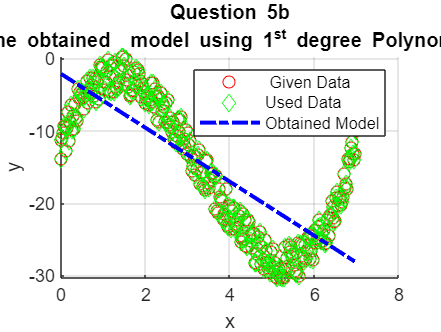

   xtest = x;
   
   px = zeros(length(xtest),1);
   powers = 0:deg;
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
   end
   %plots
    figure
   hold on
   plot(x,y,'ro')
 plot(x,y,'gd')
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Used Data','Obtained Model')
   grid on
   title({'Question 5b';'The obtained  model using 1^{st} degree Polynomial'})

**A polynomial degree of one can only represent a linear relationship between the input and output variables whereas as shown in the graph we have a nonliner relationship with our input and output variables. Therefore, we need a higher order model to better fitting. **

c) In this part we will use a higher order model (a polynomial of order 6), but only a limited amount of input data points to generate this model (we will use only** 15 data points)**. Use QR decomposition function to find the polynomial coefficients for the **6th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg = 6; %polynomial degree
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp,0);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
%z = forward_sub(Q', y);
z = Q' * y 

z =    55.8552
  -28.4791
   -1.5369
  -19.8774
    1.3027
    2.2975
   -2.5582


Ar = backward_sub(R, z);

We can test this model by evaluating $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5c, and explain the cause of what you see.**

**The obtained model appears to be a good model. It fitted pretty well with the value. They exhibit the same pattern.  It achieved a higher accuracy compared with the linear model in the previous section. A 6th degree model is versatile. It can caoture curves and bends that cannot be represented by lower level models. **

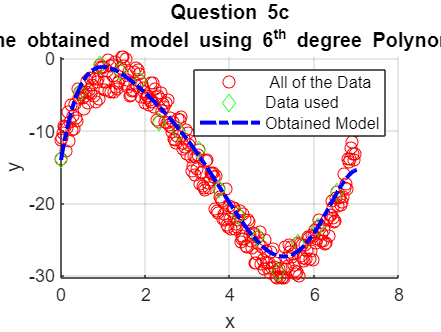


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' All of the Data','Data used','Obtained Model')
   title({'Question 5c';'The obtained  model using 6^{th} degree Polynomial'})
   grid on

d ) In this part we will use a polynomial of order **14,**  again this will be used with limited amount of data (we will use only** 15 data points, same as part c**). Use QR decomposition function to find the polynomial coefficients for the **14th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg =14

deg = 14

x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp, 0);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   
%z = forward_sub(Q', y);
z = Q' * y 

z =    55.8552
  -28.4791
   -1.5369
  -19.8774
    1.3027
    2.2975
   -2.5582
    1.7235
    0.7271
   -0.9865


Ar = backward_sub(R, z);


We can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5d, and explain the cause of what you see.**

**It is not a good model. Only parts of the graph exhibit the same pattern with the obtained model. As the degree of of model used is really high for this part of the data, it is prone to overfitting. **

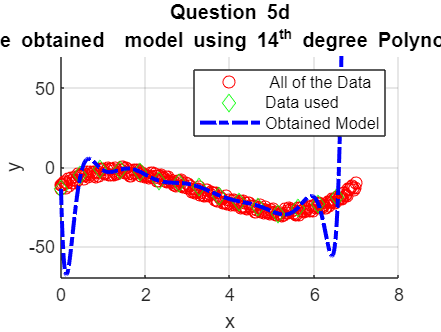


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure('Name','Question 5d','NumberTitle','off')
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   ylim([-70 70])
   legend(' All of the Data','Data used','Obtained Model')
 title({'Question 5d';'The obtained  model using 14^{th} degree Polynomial'})
   grid on

## Appendix 

## * Implement the Cholesky Decompositon fucntion here.*

function L =  CholeskyDecompositon(M)
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
    
end
%L = zeros(size(M));
% Write your code here.
n = size(M,1);
L = zeros(n);
for j=1:n
    for i=j:n
         if (i == j)
                L(j, j) = sqrt(M(j, j) - L(j, 1:j-1) * L(j, 1:j-1)');
            else
                L(i, j) = (M(i, j) - L(i, 1:j-1) * L(j, 1:j-1)') / L(j, j);
        end
    end
end
end

## *Implement Least Square Solver for Cholesky here*

function x = LeastSquareSolver_Cholesky(A,b)
% get M = A^T A
M = A'*A;

% write your code here
% Step 1. Call the choesky function written in part (a) to get Lower triangular matrix,L
L = CholeskyDecompositon(M);
   % M = L L^T

% Step 2. Use the forward substitution function named  ForwardSubs() proivded in the appendix
y = forward_sub(L, A'*b); 
% Step 3. Use the backward substitution function BackwardSubs() proivded in the appendixh--
x = backward_sub(L', y); 

end

## *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% n is the degree of the polynomial
% x is the vector of input data
[row, column] = size(x);
M = zeros(row,n+1);
for i = 0:n
    M(:,i+1) = x.^i;
end
end


## *Implement QR Methods here*

- *Classical GramSchmidt *

*pseudocode in power point 9 page 14*

function [Q,R] = gschmidt(A)
   % A is the input matrix- 
   % A could be a overdetermined matrix or a square matrix
   % Q is orthonormal matrix 
   % R is the upper triangular matrix 
   
   [n, m] = size(A);
   Q = zeros(n, m); 
   R = zeros(m, m);
   R(1,1)= norm(A(:, 1));
   Q(:,1) = A(:, 1)/R(1,1);

   for j = 2 : m
       P = zeros(n, 1);
       for i = 1 : j-1
           R(i, j) = Q(:, i)' * A(:, j);
           P = P + R(i, j) * Q(:, i);
       end
       v = A(:, j) - P; 
       R(j,j) = norm(v);
       Q(:, j) = v/R(j,j);
   end
end



- *Modified Gram-Schimdt*

% page 16 lecture 9
function [Q,R] = mgschmidt(A)
   
   [n, m] = size(A);
   Q = zeros(n, m); 
   R = zeros(m, m);

   for i = 1:m
       R(i, i) = norm(A(:, i)); 
       Q(:, i) = A(:, i)/R(i, i); 
       for j = i+1 : m
           R(i, j) = Q(:, i)' * A(:, j);
           A(:, j) = A(:, j) - R(i, j)*Q(:, i);
       end
   end
end

   

## *Function to generate Hilbert Matrix is provided here*

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end

forward/backward sub

function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
%    YOUR CODE GOES HERE

% initialization
[m, n] = size(L);
y = zeros(m, 1); 

for i = 1 : m
    y(i) = (b(i)-(L(i,1:i-1)*(y(1:i-1))))/L(i, i);
end

end 

function X = backward_sub(U,y)
% X is the vector
% U is the upper triangular matrix
%    WRITE YOUR CODE HERE
[n, m] = size(U);
X = zeros(n, 1);

for i = n : -1 : 1 
    X(i) = (y(i) - U(i, i+1:n)*(X(i+1:n)))/U(i, i);
end
end 


